f = @(x) x.^3+x.^2-x;
%Flip function (change sign) to find maximum because maximum will be
%minimum
g = @(x) -f(x)

g = function_handle with value:
    @(x)-f(x)


xx = linspace(-3,0);


%find minimum on Interval -3;0
min = fminbnd(f,-3,0)

min =   -2.999957626198658



%find maximum on Interval -3;0
max = fminbnd(g,-3,0)

max =   -1.000003271286377



disp("green => -f, blue => f")

green => -f, blue => f


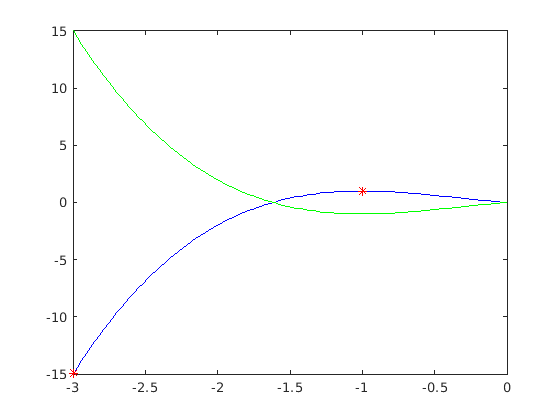

plot(xx,f(xx), "b",[max,min],[f(max),f(min)],"*r")
hold on
plot(xx,g(xx), "g")
hold off